# Intro to Machine Learning Examples Script

## Online Bayes' Decision Boundary Example

Consider a two category calssification problem with two-dimensional feature vector $X=\left(x_1 ,x_2 \right)\ldotp$                                                 The two categories are $\omega_1 \;$and $\omega_2$. 


$$\begin{array}{l}
p\left(X|\omega_1 \right)~N\left(0,\Sigma_1 \right),\\
p\left(X|\omega_2 \right)~N\left(\left\lbrack \begin{array}{c}
1\\
2
\end{array}\right\rbrack ,\Sigma_2 \right),\\
P\left(\omega_1 \right)=P\left(\omega_2 \right)=\frac{1}{2},\\
\textrm{and}\\
\Sigma_1 =\left\lbrack \begin{array}{cc}
2 & 0\\
0 & 2
\end{array}\right\rbrack ,\Sigma_2 =\left\lbrack \begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right\rbrack ,
\end{array}$$


**(a.)** Calculate the Bayes decision boundary

**(b.) ** Using MATLAB, generate 100 patterns from each of the two class-conditional densities and plot them in the two-dimensional feature space. Also draw the decision boundary on this plot

**(c.)** Generate 10,000 additional test pattern of each class and determine the empirical error rate based on the decision boundary in (a.) 

**Answer:**

You can find the decision boundary analytically. For Bayesian hypothesis testing, the decision boundary corresponds to the values of $X$ that hafve equal posteriors, i.e., you need to solve:

#### 
$$p\left(X|\omega_1 \right)p\left(\omega_1 \right)=p\left(X|\omega_2 \right)p\left(\omega_2 \right)$$


for $X=\left(x_1 ,x_2 \right)$

With equal priors, this decision rule is the same as the likelihood decision rule, i.e., : 

#### 
$$\frac{\exp \left\lbrace -\frac{1}{2}{\left(X-\mu_1 \right)}^T \Sigma_1 \left(X-\mu_1 \right)\right\rbrace }{\sqrt{\left(2\pi \right)\det \left(\Sigma_1 \right)}}=\frac{\exp \left\lbrace -\frac{1}{2}{\left(X-\mu_2 \right)}^T \Sigma_1 \left(X-\mu_2 \right)\right\rbrace }{\sqrt{\left(2\pi \right)\det \left(\Sigma_2 \right)}}$$


Plugging min the values for the means and covariance matrices and simplifying, you get:

#### 
$$-\frac{2}{2}X^T X-\frac{1}{2}\log \;4\pi^2 -\frac{1}{2}\log \;2=-\frac{1}{2}{\left(X-b\right)}^T \left(X-b\right)-\frac{1}{2}\;\log \left(4\pi^2 \right)$$


Solving for $X:$

#### 
$$x_1^2 +x_2^2 +2x_1 +4x_{2\;} +\log \left(2\right)-5=0$$


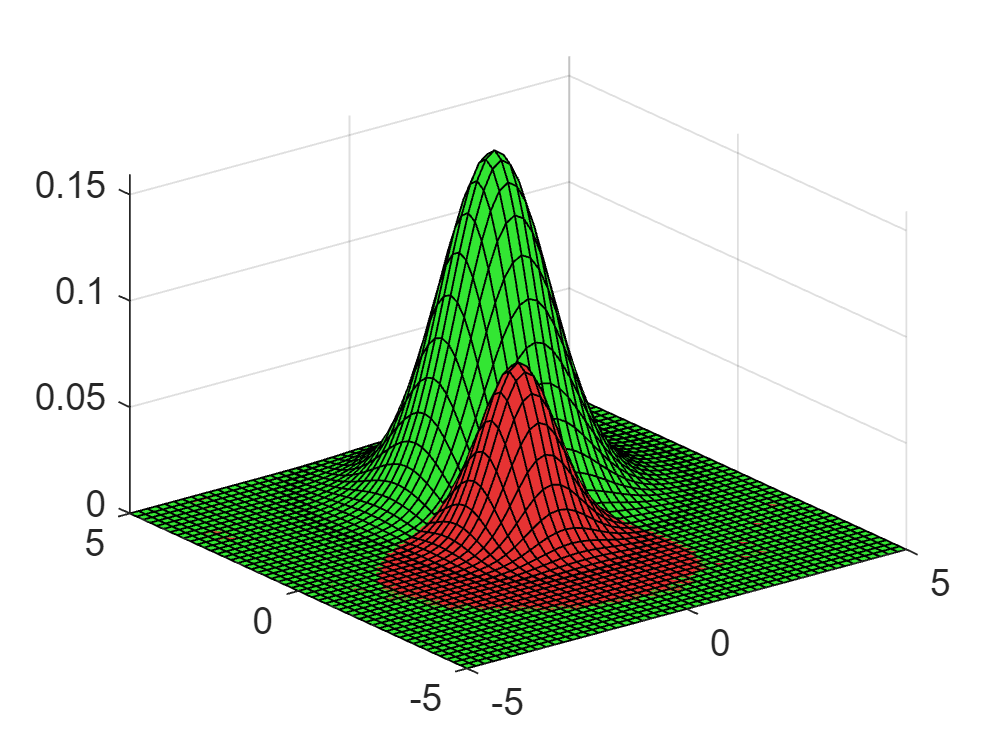

clear all; close all
%Natural parameters
mu1 = [0; 0];
sigma1 = [2 0; 0 2];
mu2 = [1; 2];
sigma2 = [1 0; 0 1];

%Gaussians as anonymous functions 
gauss1 = @(x1, x2) exp(-0.5*([x1;x2]-mu1)'*sigma1*([x1;x2]-mu1))/(2*pi*sqrt(det(sigma1)));
gauss2 = @(x1, x2) exp(-0.5*([x1;x2]-mu2)'*sigma2*([x1;x2]-mu2))/(2*pi*sqrt(det(sigma2)));
[x1, x2] = meshgrid(-5:0.2:5); %generate grid
g1 = arrayfun(gauss1, x1, x2); %apply functions to grid points
g2 = arrayfun(gauss2, x1, x2);
surf(x1, x2, g1, 'FaceColor', [0.9 0.2 0.2]);  %plot
hold on
surf(x1, x2, g2, 'FaceColor', [0.2 0.9 0.2]);

gdiff = g1 - g2; %get difference points
C = contours(x1, x2, gdiff, [0,0]); %get points where contour is zero
%get seperate coordinates of contour
x1s = C(1, 2:end);
x2s = C(2, 2:end);
%interporlate contour on gaussian 1
boundry = interp2(x1, x2, g1, x1s, x2s);
%plot it

## Binomial Distribution Example

Examine and plot the success rate for an example of Amazon Reviews given the positive/negative reviews

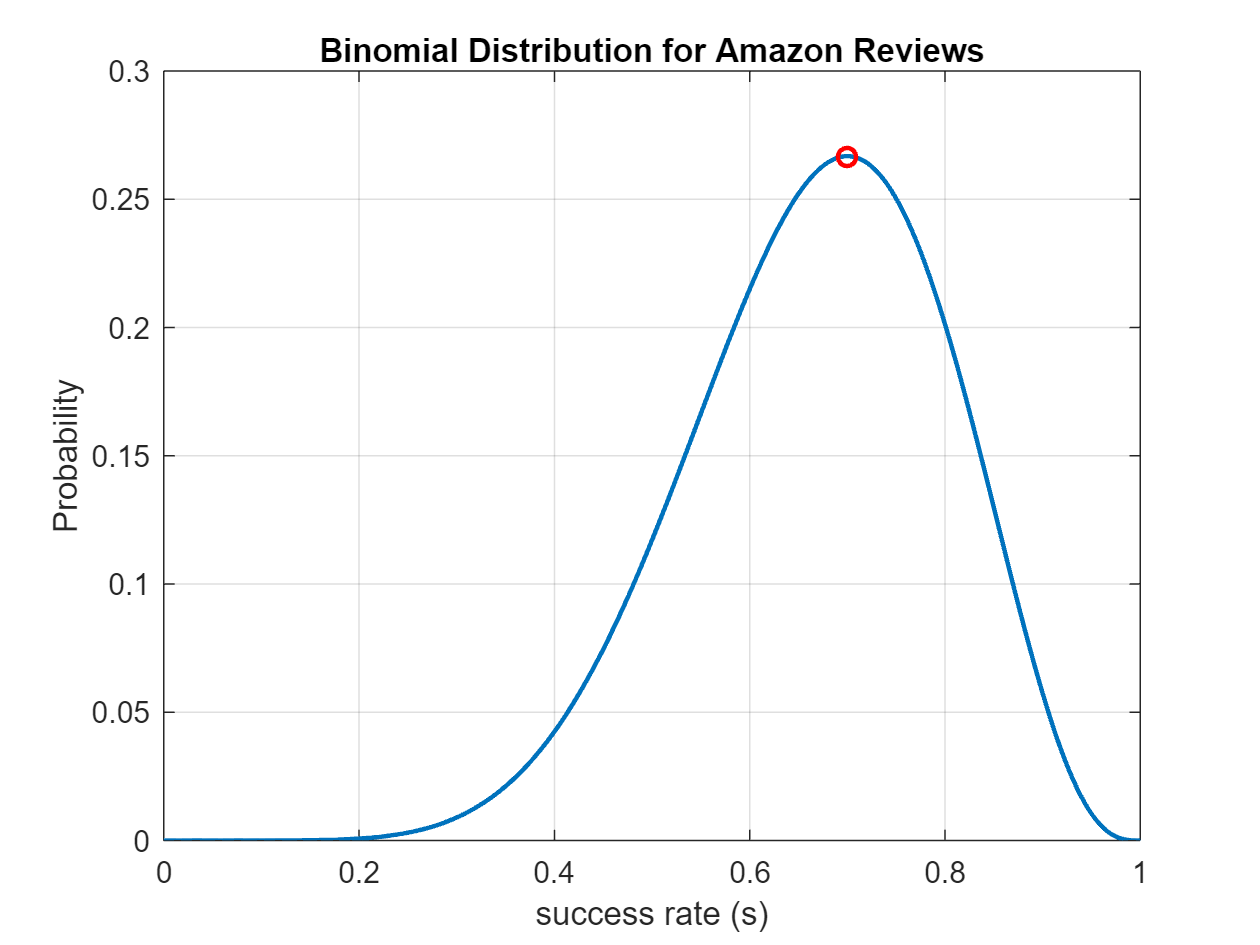

% Suppose 50 reviews left on Amazon product with 48 positives and 2
% negative reviews
n = 10; % total number of reviews
k = 7 ; % number of positive reviews
binoFact = nchoosek(n,k);
s = 0:0.001:1;
P_data_given_s = binoFact.*(s).^(k).*(1-s).^(n-k);
[~,maxValue] = max(P_data_given_s);
s_max = P_data_given_s(maxValue);
figure()
plot(s,P_data_given_s,'LineWidth',1.5), xlabel('success rate (s)'), ylabel('Probability')
title('Binomial Distribution for Amazon Reviews'), grid on, hold on
plot(s(maxValue),s_max,'ro','LineWidth',1.5), hold off

fprintf('The maximum value for success rate is %.3f',s_max)

The maximum value for success rate is 0.267

fprintf('The Probability of value being between 0.6 <= P(h) <= 0.8 is %.3f', sum(P_data_given_s(600:800)*0.01))

The Probability of value being between 0.6 <= P(h) <= 0.8 is 0.495